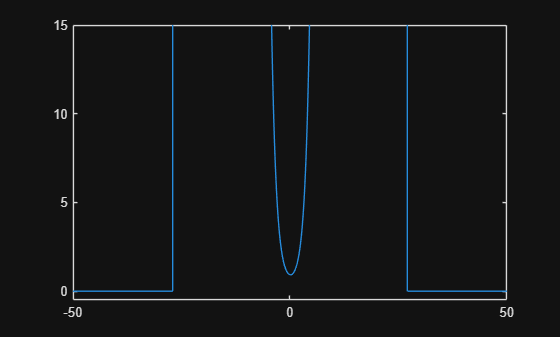

% Hey if you're reading this uhhhhhhh I shared it succesfully! Yippee!

for k = 1:50

    tau = 1.*k;

    alpha = 1;

    omega = 0.1;

    tcross = 1;

    z = @(t) 0.5 .* sin(t) .* exp(-t);

    besselsource = @(t,s) alpha .* besselj(0, omega .* sqrt(t.^2 - (s - z(t)).^2));

    Usource = @(t, s) compute_Usource(t, s, tcross, besselsource, z);

    slin = linspace(-50, 50, 2000);

    for i = 1:length(slin)
        solved_Usource(i) = Usource(tau, slin(i));
    end

    plot(slin, solved_Usource)
    axis([-50 50 -0.5 15])
    saveas(gcf, ['Lecture 11 Sourced-Field' num2str(k) '.png'])

end


function U = compute_Usource(t, s, tcross, besselsource, z)
    if t^2 >= (s - z(t))^2
        U = integral(@(tt) besselsource(tt, s), 0, tcross);
    else
        U = 0;
    end
end